# Fitting of a polynomial using least-squares method

Approximating a dataset using a polynomial equation is useful when conducting engineering calculations as it allows results to be quickly updated when inputs change without the need for manual lookup of the dataset.

More theory from [Wolfram ](https://mathworld.wolfram.com/LeastSquaresFittingPolynomial.html)

NOTE: this LiveScript requires input_check.m script in order to run

% clearing command window and workspace is OPTIONAL
clc;
clear;

## 1.Parameters of approximation

- a - Polynomial coefficient

- k - The degree of the polynomial

- N - The number of points to be regressed

- e - Error

N = input('enter the # of points to be regressed: ');
k = input('enter the degree of the polynomial: ');
clc;

title = 'Dataset of %i points, polynomial of %i degree\n ';
fprintf(title,N,k);

Dataset of 5 points, polynomial of 4 degree
 

clear title;

input_check
if wrong_input == 1
    return
end
clear wrong_input; % see input_check.m for more details

m = k + 1;
MatrixA=zeros(m,m);

**Load points from file**

M = load('data.txt');
X = M(1,1:N);
Y = M(2,1:N);
clear M;

## 2.Creation of matrices

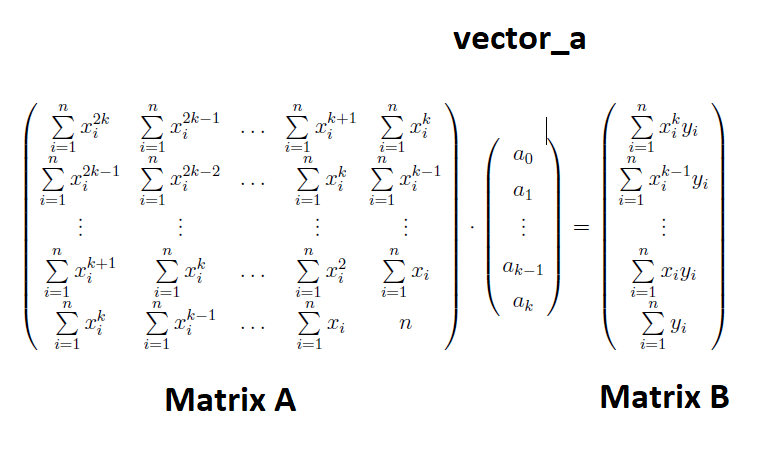

**Matrix A:**

Creation of vector in which future elements of A will be stored. Length of vector is equal to # of calculations + 1 for N.

semi_results = 1:(2*k)+1;

semi_results(1,1) = N;

Loop which calculates and fills each element into "results" vector

for pwr = 1:2*k
    semi_results(1,1+pwr)=sum(X.^pwr);
end
clear pwr;

% after fill-up, vector needs to be flipped 
semi_results=fliplr(semi_results);

Filling the matrix A with "results" array, row by row

for i = 1:m
    warning('off');
    MatrixA(i,:) = semi_results(1,i:m+j);
    j=j+1;
end 
clear i j results;

MatrixA

MatrixA =       462979       96825       20515        4425         979
       96825       20515        4425         979         225
       20515        4425         979         225          55
        4425         979         225          55          15
         979         225          55          15           5


**Matrix B**

Creation of another results vector which will be transposed into matrix B. Lenght is K + 1 for first element which is sum of Y.

semi_results = 1:m;

semi_results(1,1)=sum(Y);

for pwr = 1:k
    Xpow = X.^pwr;
    semi_results(1,1+pwr)=sum(Xpow.*Y);
end
clear m pwr Xpow;

semi_results = fliplr(semi_results);
MatrixB = semi_results'

MatrixB =         6172
        1396
         328
          82
          23


clear semi_results;

## 3.Result

vector_a = MatrixA\MatrixB

vector_a =    -0.5000
    5.5000
  -20.5000
   31.5000
  -14.0000



Results = polyval(vector_a,X);

Sum of least-squares errors.

e = sum((Results - Y).^2)

e = 1.5279e-22

Show polynomial and plot results.

polynomial_squares = poly2sym(vector_a)

$$polynomial\_squares = -\frac{4503599627409159\,x^{4}}{9007199254740992}+\frac{774056185961599\,x^{3}}{140737488355328}-\frac{2885118511314585\,x^{2}}{140737488355328}+\frac{2216615441621561\,x}{70368744177664}-\frac{7881299348005905}{562949953421312}$$

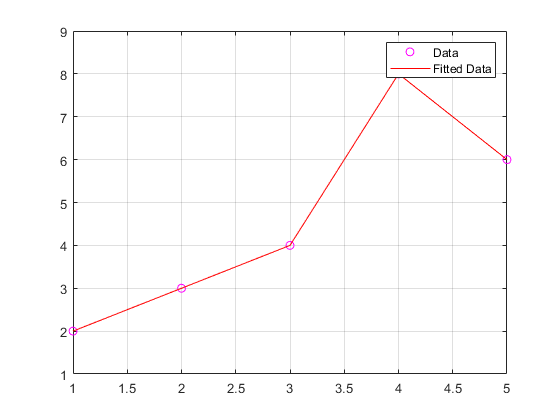


plot(X,Y, 'mo',X,Results,'-r');
grid;
legend('Data','Fitted Data');

**Verification:**

semi_results = polyfit(X,Y,k);

Results_verif = polyval(semi_results,X); 

polynomial_verif = poly2sym(semi_results)

$$polynomial\_verif = -\frac{x^{4}}{2}+\frac{11\,x^{3}}{2}-\frac{2885118511284289\,x^{2}}{140737488355328}+\frac{4433230883192971\,x}{140737488355328}-\frac{7881299347898807}{562949953421312}$$

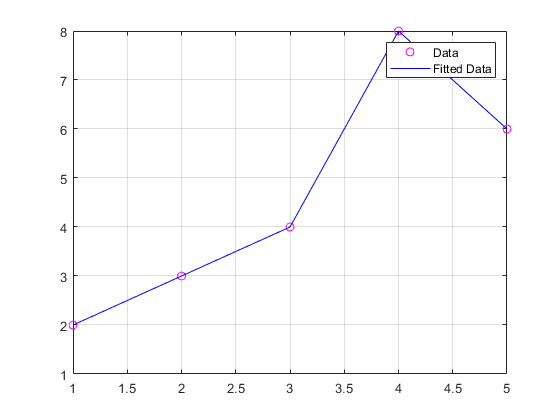


plot(X,Y, 'mo',X,Results_verif,'-b');
grid;
legend('Data','Fitted Data');


clear semi_results;

*David Polakovic, 2020*